Gradient descent

n = 10;
h = 20;
m = 2;
rng('default');
rng(2021);
y_tar = rand(m,1);
iter = 1000;
itag = 1/(2+n);
wih = 0.1*rand(h,n);
%wihtarget = rand(h,n);
who = 0.1*rand(m,h);
%whotarget = rand(m,h);
%Wih = wih - wihtarget;
%Who = who - whotarget;
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
for i = 1:iter
    H = wih*x;
    y = who*H;
    e = 0.5*norm(y-y_tar)^2;
    etraj(i) = e;
    deltwho = -itag*(y-y_tar)*H';
    deltawih = -itag*who'*(y-y_tar)*x';
    wih = wih+deltawih;
    who = who+deltwho;
end 

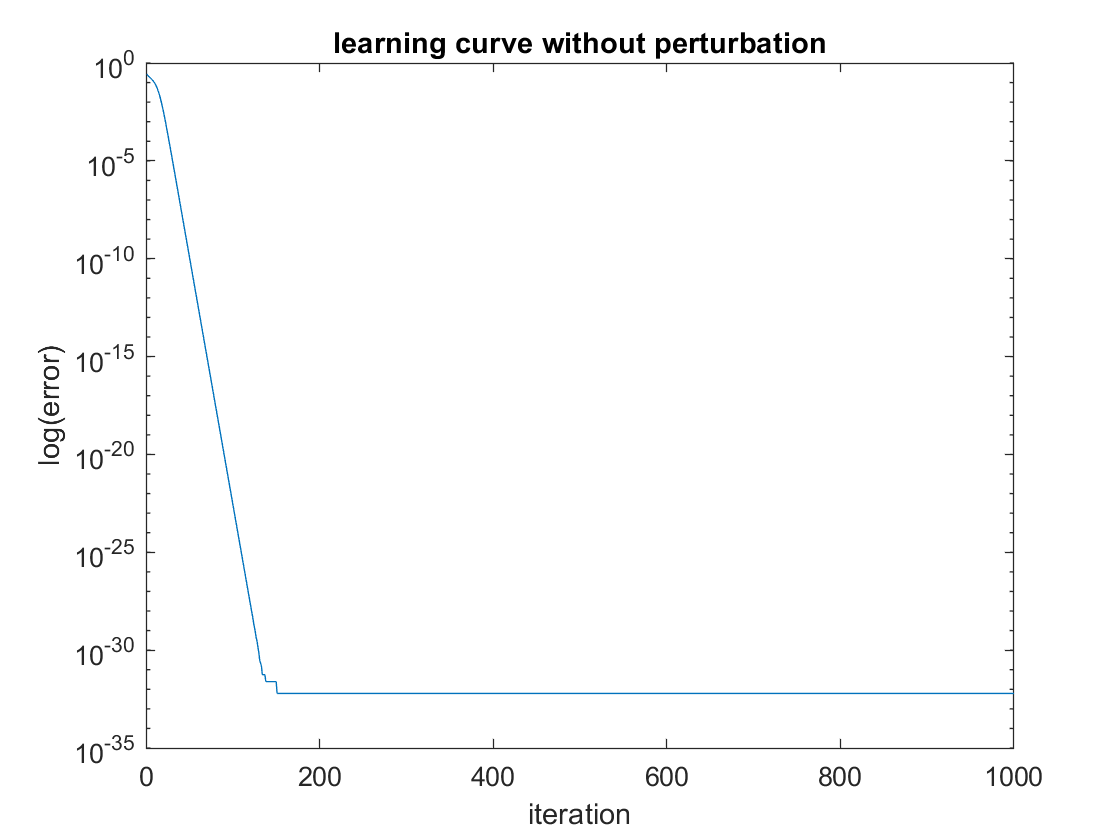

semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve without perturbation');

Node perturbation

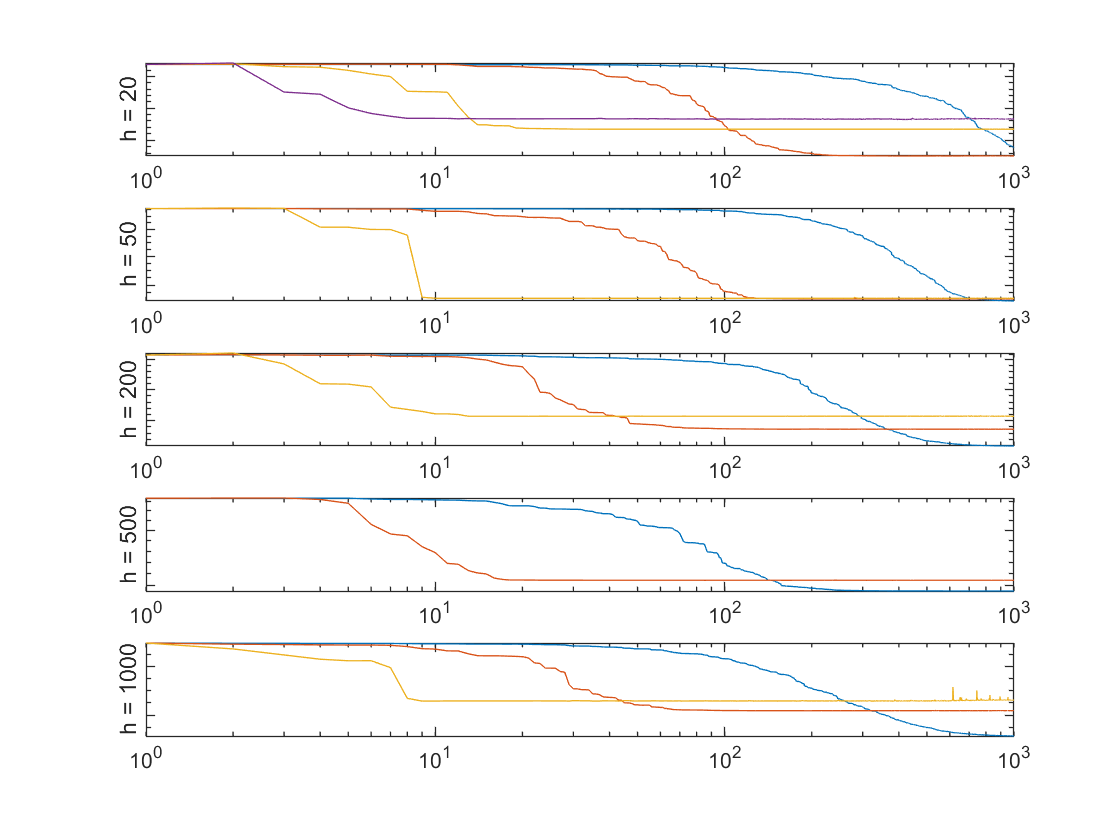

figure
n = 10;
m = 1;
sigma = 0.01;
iter = 1000;
num_run = 50;
h_M = [20 50 200 500 1000];
for k = 1:length(h_M)
h = h_M(k);
lambda1 = [0.02 0.1 0.5 1 2 5];
%itanp = (1/((m+h+2)*(n+2)))*lambda;
for p = 1:length(lambda1)
%itanp = (1/((m+h+2)*(n+2)))*lambda;
itanp = (1/((m+2)*(n+2)))*lambda1(p);
etraj_all = zeros(num_run, iter);
for j = 1:num_run
wih_np = 0.01*rand(h,n);
who_np = 0.01*rand(m,h);
x = normrnd(0,1,[n,1]);
%fix target
rng('default');
rng(20);
w_star = rand(m,n);
y_tar = w_star*x;
etraj = zeros(1,iter);
%etraj_2 = zeros(1,iter);
%eb = 0;
for i = 1:iter
% perturbation on hidden and output layers
enpo = normrnd(0,sigma,[m,1]);
enph = normrnd(0,sigma,[h,1]);
% without perturbation -> E
H = wih_np*x;
y = who_np*H;
e = 0.5*norm(y-y_tar)^2;
g_e = norm(who_np*wih_np-w_star)^2;
% with perturbation -> E_per
H_per = wih_np*x+enph;
y_per = who_np*H_per+enpo;
eper2 = 0.5*norm(y_per-y_tar)^2;
etraj(i) = g_e;
%etraj_2(i) = e;
% weights update 
deltawho_np = -(itanp/sigma^2)*(eper2-e)*enpo*H';
deltawih_np = -(itanp/sigma^2)*(eper2-e)*enph*x';
%eb = (1-alpha)*eb+alpha*eper2;
wih_np = wih_np+deltawih_np;
who_np = who_np+ deltawho_np;
end
if etraj(end) <= etraj(1)
etraj_all(j,:) = etraj;
end
end
etraj_all = etraj_all(any(etraj_all,2),:);
etraj_avg = mean(etraj_all);
subplot(length(h_M),1,k)
loglog(etraj_avg)
ylabel('h = '+string(h))
set(gca,'YTickLabel',[]);
hold on;
end
end

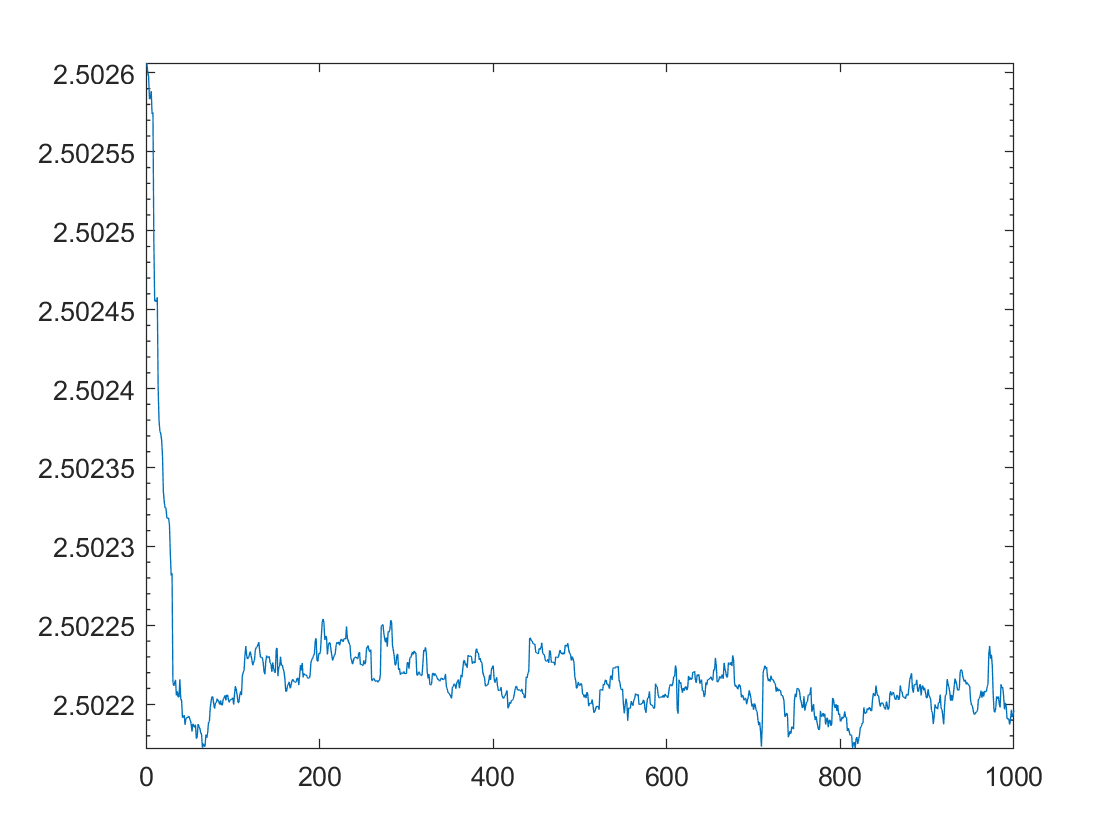

etraj_avg = mean(etraj_all);
figure
semilogy(etraj_avg)

yl = yticklabels;
fite = log10(etraj_avg);
%[k, intercept] = polyfit(100:1:850,fite(100:850),1);

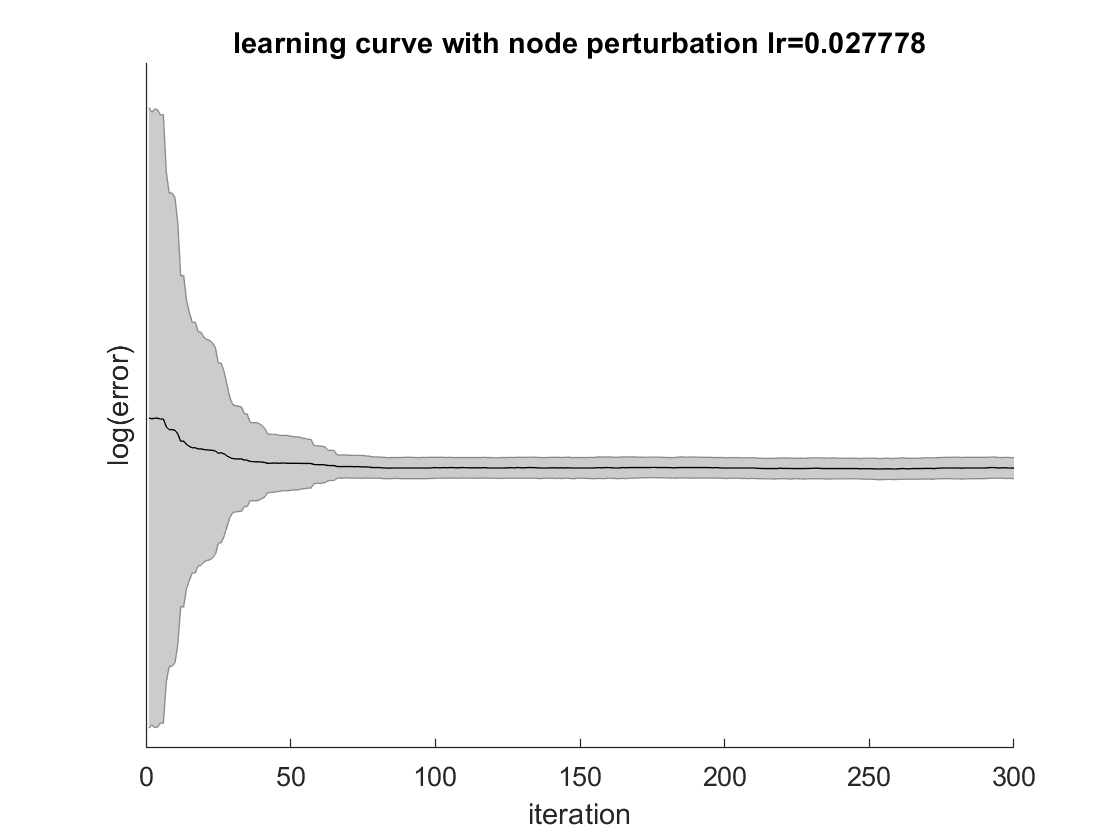

%etraj_log = log10(etraj_all);
etraj_log_avg = log10(etraj_avg);
etraj_sde = 0.434*std(etraj_all)./(etraj_log_avg*sqrt(num_run));
iter_plot = 1:1:iter;
figure
%hold on;
shadedErrorBar(iter_plot,etraj_log_avg,etraj_sde)
%set(gca, 'YScale', 'log')
%ytick=10.^(-9:0);
%yticklab = cellstr(num2str(round(-log10(ytick(:))), '10^-^%d'));
yticks([-7 -6 -5 -4 -3 -2 -1]);
set(gca,'YTickLabel',yl,'TickLabelInterpreter','tex')
%semilogy(etraj);
%hold on
%semilogy(etraj_2);
xlabel('iteration');
ylabel('log(error)');
title('learning curve with node perturbation lr='+string(itanp));

Analysis

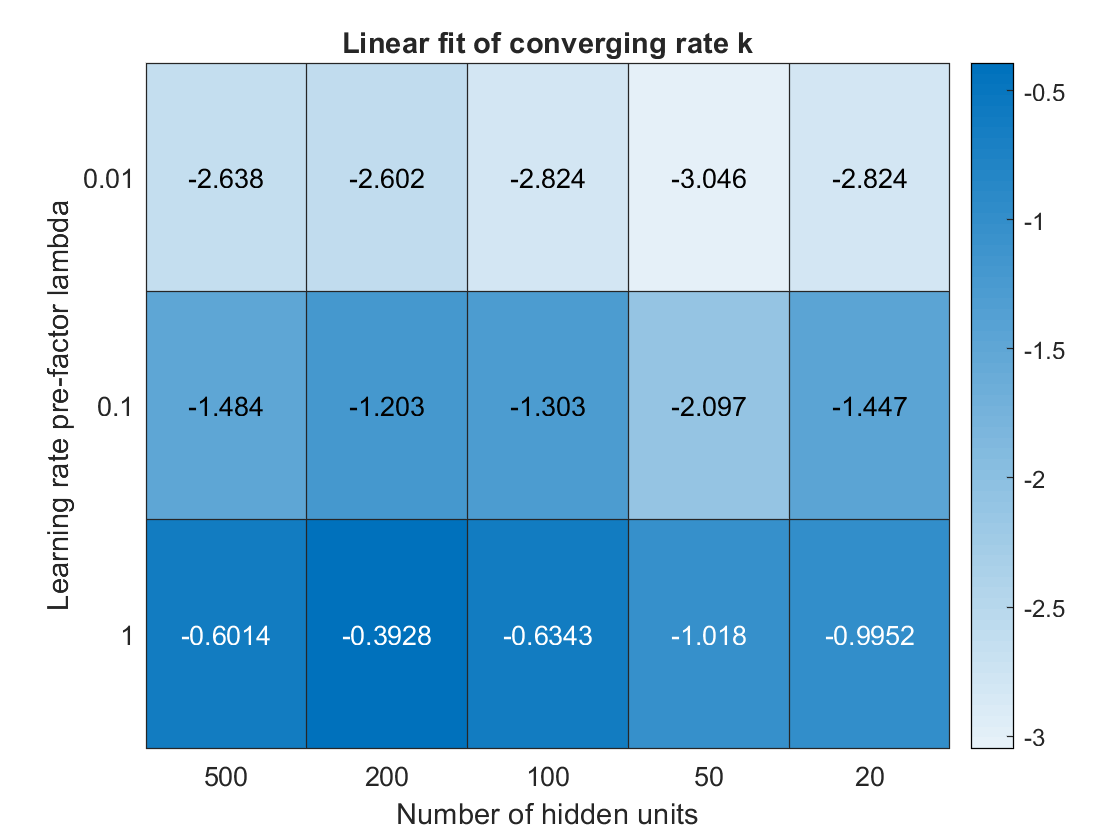

ktable = [-0.0023 -0.0025 -0.0015 -0.0009 -0.0015; -0.0328 -0.0627 -0.0498 -0.0080 -0.0357; -0.2504 -0.4048 -0.2321 -0.09583 -0.1011];
log_k = log10(-ktable);
xvalues = {'500','200','100','50','20'};
yvalues = {'0.01','0.1', '1'};
h = heatmap(xvalues,yvalues,log_k);
h.Title = 'Linear fit of converging rate k';
h.XLabel = 'Number of hidden units';
h.YLabel = 'Learning rate pre-factor lambda';

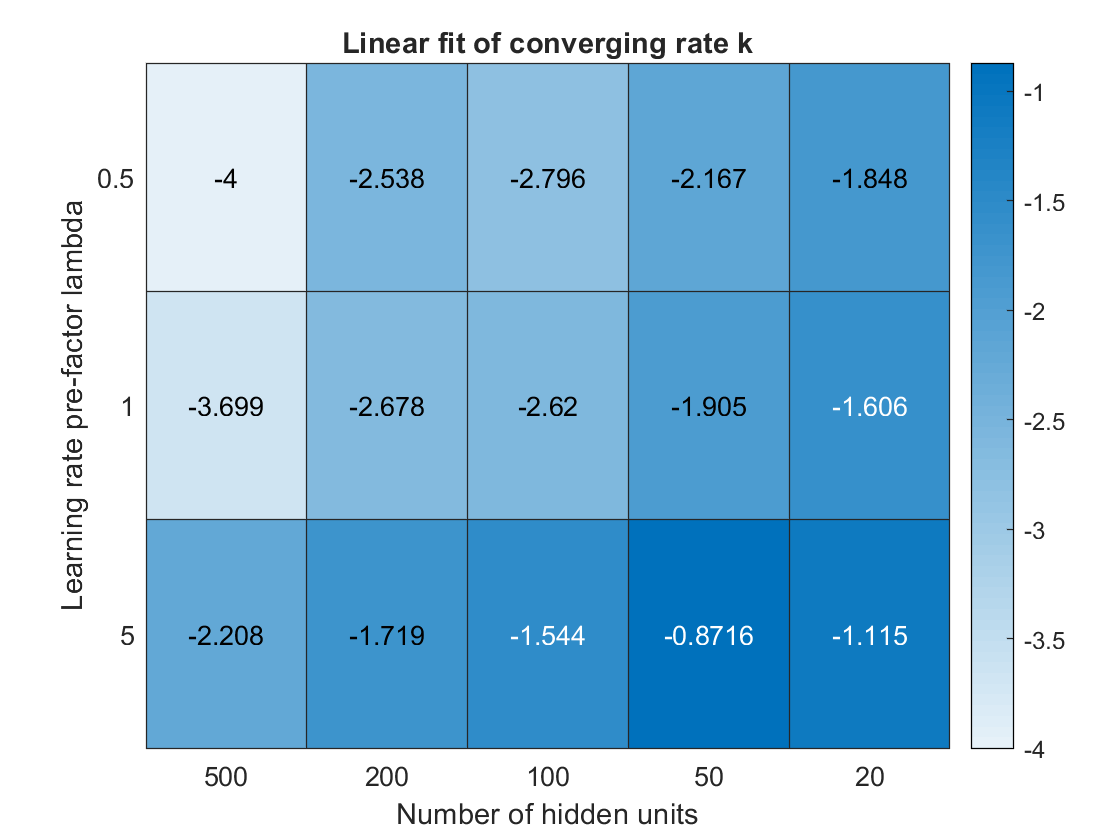

ktable = [-0.0001 -0.0029 -0.0016 -0.0068 -0.0142; -0.0002 -0.0021 -0.0024 -0.01245 -0.0248; -0.0062 -0.0191 -0.0286 -0.1344 -0.0768];
log_k = log10(-ktable);
xvalues = {'500','200','100','50','20'};
yvalues = {'0.5','1', '5'};
h = heatmap(xvalues,yvalues,log_k);
h.Title = 'Linear fit of converging rate k';
h.XLabel = 'Number of hidden units';
h.YLabel = 'Learning rate pre-factor lambda';